# **N-S Equstion Solver (Unsteady, Incompressible 2D) **

**Author:- Kshitij Gupta (developed as a part of internship at IITD)**

**Note* **Linearised Navier-Stokes doesn't work with this MAC formulation. Time step should considered carefully for explicit solver (generally smaller than implicit or semi-implicit solvers)

## **Method used: **

**Marker and Cell method:- **Staggered grid is used to solve the various parameters. u and v velocity is solved on edges and pressure p is solved at grid centre.

**FDM:- **Finite difference method is used

## **Important Equations:**

The Navier-Stokes equations:

    
$$\begin{array}{l}
\nabla \cdot \;\;\mathbf{u}\;=0\\
\frac{\partial \mathbf{u}}{\partial t}+\nabla \cdot (\mathbf{u}\mathbf{u})=\frac{\nabla \mathbf{p}}{\rho }+\nu \nabla^2 \mathbf{u}+\Delta \ldotp \mathit{\mathbf{f}}
\end{array}$$


The pressure Poisson equation: $$\frac{\nabla^2p}{\rho} = - \nabla \cdot \nabla \cdot (\bf{u}\bf{u})+\nabla\cdot{f}$

## **Setup domain and flow related initial variables**

=======================================================================================

**Parameters**

clc

Lx = 1; % Length in x-direction
Ly = 1; % Length in y-direction
Nx = 10; % Number of grid points in x-direction
Ny = 10; % Number of grid points in y-direction
Re = 100; % Reynolds number
rho=1000;
g=9.81;
tolerance = 1e-6; % Convergence tolerance
U_wall=0;
Amp=1;
n=1;
h=1;
Fd=1;
alpha=1;
omega= 10;
Np = Nx*Ny - 1;

**Discretization**

dx = Lx / Nx;
dy = Ly / Ny;
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);
[X, Y] = meshgrid(x, y);
cornerX = 0; cornerY = 0;

**Plotting the domain **

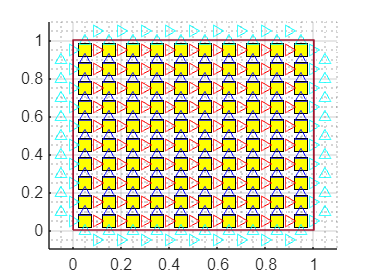

draw(Lx, Ly, Nx, Ny, dx, dy, cornerX, cornerY);

**Initialize velocity and pressure fields**

u = zeros(Ny, Nx);
v = zeros(Ny, Nx);
p = zeros(Ny, Nx);
u_new = zeros(Ny, Nx);
v_new = zeros(Ny, Nx);
p_new = zeros(Ny, Nx);
p_old=zeros(Ny, Nx);

**Time stepping parameters**

dt = 0.000001;
max_iter = 10000;

## **Main Function**

=======================================================================================

disp('select 1 for linear and 2 for non-linear Navier Stokes solver');

select 1 for linear and 2 for non-linear Navier Stokes solver


Navier_stokes = input('Enter the your choice: ', 's');

sol_index=1;
for iter = 1:max_iter

     % Calculating velocities for constant vecicle velocity

     %omega = sqrt(n * h * tanh(n * pi)/(Fd^2));  
     U_wall = Amp*omega*cos(omega*dt*iter); 

    switch Navier_stokes

        case '1'
         [u, v, p] = navier_stokes_solver_1(u, v, p, dx, dy, dt, tolerance, U_wall, alpha);
         if mod(iter, 100) == 0
         fprintf('Iteration: %d\n', iter);
         pause(0.01);  
         end

        case '2'
         [u, v, p] = navier_stokes_solver_2(u, v, p, dx, dy, dt, Re, tolerance, U_wall);
         if mod(iter, 100) == 0
          fprintf('Iteration: %d\n', iter);
          pause(0.01);  
          % Saving the solution after every dt
         end
          
    end 
    if mod(sol_index, 10000) == 0
          for i = 1:Nx
            for j = 1:Ny
            u_unsteady(sol_index,i,j) = u(i,j);
            v_unsteady(sol_index,i,j) = v(i,j);
            p_unsteady(sol_index,i,j) = p(i,j);
            end
          end
    end

    sol_index=sol_index+1;
end

Iteration: 100
Iteration: 200
Iteration: 300
Iteration: 400
Iteration: 500
Iteration: 600
Iteration: 700
Iteration: 800
Iteration: 900
Iteration: 1000
Iteration: 1100
Iteration: 1200
Iteration: 1300
Iteration: 1400
Iteration: 1500
Iteration: 1600
Iteration: 1700
Iteration: 1800
Iteration: 1900
Iteration: 2000
Iteration: 2100
Iteration: 2200
Iteration: 2300
Iteration: 2400
Iteration: 2500
Iteration: 2600
Iteration: 2700
Iteration: 2800
Iteration: 2900
Iteration: 3000
Iteration: 3100
Iteration: 3200
Iteration: 3300
Iteration: 3400
Iteration: 3500
Iteration: 3600
Iteration: 3700
Iteration: 3800
Iteration: 3900
Iteration: 4000
Iteration: 4100
Iteration: 4200
Iteration: 4300
Iteration: 4400
Iteration: 4500
Iteration: 4600
Iteration: 4700
Iteration: 4800
Iteration: 4900
Iteration: 5000
Iteration: 5100
Iteration: 5200
Iteration: 5300
Iteration: 5400
Iteration: 5500
Iteration: 5600
Iteration: 5700
Iteration: 5800
Iteration: 5900
Iteration: 6000
Iteration: 6100
Iteration: 6200
Iteration: 6300
I


boundary_condition_tests(u, v);

Boundary Condition Test
Top wall u-velocity: Pass
Left and right wall u-velocity: Pass
Left and right wall v-velocity: Pass
Bottom and top wall v-velocity: Pass
Total failed boundary conditions: 0


## **Plotting of variables**

=======================================================================================

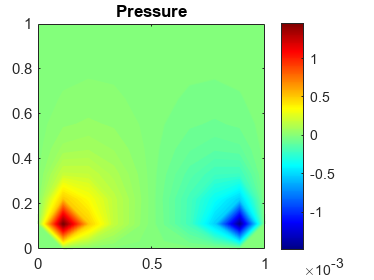


%{
figure(1);
startx = 0.0001:0.0001:1;
starty = 0.5.*ones(length(startx),1);
count = 1;
for i = 10000:10000:90000
    subplot(3,3,count)

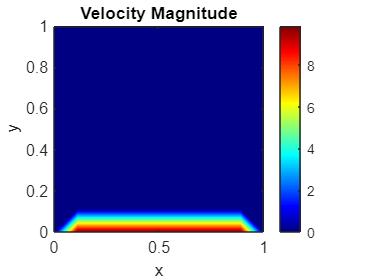

    v_sample = v_unsteady(i,:,:);
    v_sample = reshape(v_sample, [size(v_sample,2) size(v_sample,3)]);
    contourf(X,Y,v_sample, 100, 'LineStyle', 'none')
    %clim([-1 1])
    colorbar;
    colormap jet;
    xlabel('x')
    ylabel('y')
    title(['iter = ' num2str(i) ])  % Add title with time value
    count = count + 1;
end
sgtitle('v-velocity contours at Different Iterations');
%}


%{
% Plotting
figure(1);

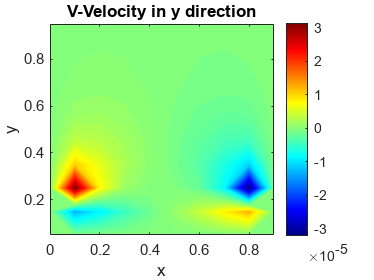

pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,2,3);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,3)');
title('Pressure Variation Over Time');

figure(2);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,2,4);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,4)');
title('Pressure Variation Over Time');

figure(3);
pressure_values = zeros(1, 100);

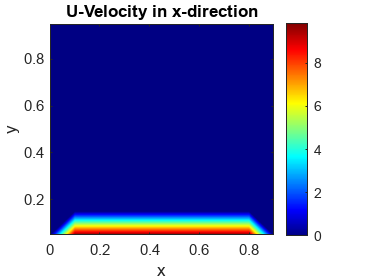

for i = 1:100
    p_sample = p_unsteady(i*50000,2,5);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,5)');
title('Pressure Variation Over Time');

figure(4);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,2,6);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,6)');
title('Pressure Variation Over Time');


figure(5);
pressure_values = zeros(1, 100);
for i = 1:100

    p_sample = p_unsteady(i*50000,2,7);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,7)');
title('Pressure Variation Over Time');

figure(6);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,2,8);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,8)');
title('Pressure Variation Over Time');

figure(7);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,2,9);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (2,9)');
title('Pressure Variation Over Time');

figure(8);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,3,2);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (3,2)');
title('Pressure Variation Over Time');

figure(9);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,3,4);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (3,4)');
title('Pressure Variation Over Time');

figure(10);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,3,5);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (3,5)');
title('Pressure Variation Over Time');

figure(11);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,3,6);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (3,6)');
title('Pressure Variation Over Time');

figure(12);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,3,7);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (3,7)');
title('Pressure Variation Over Time');

figure(13);
pressure_values = zeros(1, 100);
for i = 1:100
    p_sample = p_unsteady(i*50000,3,8);
    pressure_values(i) = p_sample;
end
iteration = 50000:50000:5000000;
plot(iteration, pressure_values, '-o'); 
xlabel('Time Intervals');
ylabel('Pressure at idex (3,8)');
title('Pressure Variation Over Time');
%}


%Plot Pressure Field
figure(9);
[~,hp] = contourf(X, Y, p, 100);
colormap jet;
colorbar;
set(hp,'LineColor','auto');
title('Pressure');
pause(0.01);


% Plot velocity Magnitude
Velocity=zeros(Nx, Ny);
for i=1:Nx
    for j=1:Ny
            Velocity(i,j) = sqrt(u(i,j)^2 + v(i,j)^2);
    end
end
figure(2);
[~,hvel] = contourf(X, Y, Velocity, 100);
colormap jet;
colorbar;
set(hvel,'LineColor','none');
title('Velocity Magnitude')
xlabel('x');
ylabel('y');

% Plotting V-velocity 
xv = zeros(1,Nx);
yv = zeros(1,Ny);
for i = 1:Nx
        xv(i)=((i-1)*dx)+cornerX;
end
for j = 1:Ny
        yv(j)=((j-1)*dy)+dy/2+cornerY;
end
%xu(Nx+1) = cornerX+Lx;
for i=1:Nx
    for j=1:Ny
        Xv(i,j) = xv(i);
        Yv(i,j) = yv(j);
    end
end
figure(3);
[~,hv]=contourf(Xv,Yv,v',100);
colormap jet;
colorbar;
set(hv,'Linecolor','none')
title('V-Velocity in y direction');
xlabel('x');
ylabel('y');


 %Plotting U-velocity 
xu = zeros(1,Nx);
yu = zeros(1,Ny);
for i = 1:Nx
        xu(i)=((i-1)*dx)+cornerX;
end
for j = 1:Ny
        yu(j)=((j-1)*dy)+dy/2+cornerY;
end
%xu(Nx+1) = cornerX+Lx;
for i=1:Nx
    for j=1:Ny
        Xu(i,j) = xu(i);
        Yu(i,j) = yu(j);
    end
end
figure(4);
[~,hu]=contourf(Xu,Yu,u',100);
colormap jet;
colorbar;
set(hu,'Linecolor','none')
title('U-Velocity in x-direction');
xlabel('x');
 ylabel('y');




%Plot stream function
%{
[U,V,ipq] = find_cell_centered(u, v, p, Np, Nx ,Ny ) ;

for i=1:m
    for j=1:n
            uV(i,j) = U(ipq(i,j));
            vV(i,j) = V(ipq(i,j));
    end
end

uV=uV';
vV=vV';


figure(5);
q = quiver(X,Y,u',v');
axis([0 1 0 1])
title('Velocity Vector and Steamlines')
q.AutoScale = 'on';
q.AutoScaleFactor = 3;
q.Color = 'red';
starty = (0:0.05:22);
startx = 0.5*ones(size(starty));
streamline(X,Y,u',v',startx,starty)
%}


**Plotting the domain with annotations**

In the following figure: 

- Square are the cell center where pressure is evaluated.

- Arrow heads are the velocities. Cyan: boundary conditions. Red: solution x direction, blue: y direction

function draw(Lx, Ly, Nx, Ny, dx, dy, cornerX, cornerY)

figure();
hold on

%Pressure
for i = 1:Nx
    for j = 1:Ny
        plot(((i-1)*dx)+dx/2+cornerX,((j-1)*dy)+dy/2+cornerY,'bs', ...
            'LineWidth',1,...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor',[1 1 0],...
            'MarkerSize',10)
    end
end

%U
for i = 2:Nx
    for j = 1:Ny
        plot(((i-1)*dx)+cornerX,((j-1)*dy)+dy/2+cornerY,'r>')
    end
end
%V
for i = 1:Nx
    for j=2:Ny
        plot(((i-1)*dx)+dx/2+cornerX,(j-1)*dy+cornerY,'b^')
    end
end

%Left U and V
i = 1; %U
for j=1:Ny
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
i = 0; %V
for j=2:Ny
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

%Right U and V
i = Nx+1; %U
for j=1:Ny
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
i = Nx+1; %V
for j=2:Ny
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

%Bottom U and V
j = 0; %U
for i=2:Nx
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
j = 1; %V
for i=1:Nx
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

%Top U and V
j = Ny+1; %U
for i=2:Nx
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
j = Ny+1; %V
for i=1:Nx
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end


%Domain
plot([cornerX cornerX+Lx cornerX+Lx cornerX cornerX], ...
    [cornerY cornerY cornerY+Ly cornerY+Ly cornerY],'LineWidth',1)

axis([cornerX-dx cornerX+Lx+dx cornerY-dy cornerY+Ly+dy])
hold off
grid on
grid minor
end

**Navier stokes linear solver**

function [u_new, v_new, p_new] = navier_stokes_solver_1(u, v, p, dx, dy, dt, tolerance, U_wall, alpha)
[Ny, Nx] = size(u);

% Initialize temporary fields
u_new = u;
v_new = v;
p_new = p;


% Calculate the tentative velocity (u*) using momentum equations
for i = 2:Ny - 1
    for j = 2:Nx - 1

        % for u direction 

        pressure = (p(i,j+1) - p(i,j-1))/2*dx;

        u_new(i, j) = u(i, j) - dt * alpha* pressure;

        % for v direction 

        pressure = (p(i,j+1) - p(i,j-1))/2*dy;

        v_new(i, j) = v(i, j) - dt * pressure ;

      
    end
end

% Pressure correction (Poisson equation)

maxe = 1;
while maxe > tolerance
    p_old = p_new;
    for i = 2:Ny - 1
        for j = 2:Nx - 1
            p_new(i, j) = (1 / 4) * (p_old(i, j + 1) + p_old(i, j - 1) ...
                + p_old(i + 1, j) + p_old(i - 1, j) ...
                - dx * (u_new(i, j-1) - u_new(i, j+1)) / 2 ...
                - dy * (v_new(i-1, j) - v_new(i+1, j)) / 2);
        end
    end
    maxe = max(max(abs(p_new - p_old)));
end

%Update velocity with pressure correction using the initial pressure field
for i = 2:Ny - 1
    for j = 2:Nx - 1
        u_new(i, j) = u_new(i, j) - dt * (p_new(i, j+1) - p_new(i, j+1)) / (2 * dx);
        v_new(i, j) = v_new(i, j) - dt * (p_new(i+1, j) - p_new(i-1, j)) / (2 * dy);
    end
end

% Boundary conditions
u_new(1,: ) =  U_wall;
u_new(end, :) = 0;
u_new(:, end) = 0;
u_new(:, 1) = 0;

v_new(1, :) = 0;
v_new(end, :)= 0;
v_new(:, end) = 0;
v_new(:, 1) = 0;


%{
for j=1:Ny
    p(i,j)=0;
end

for i=2:Nx
    for j=1:Ny
        p(i,j)=(i-0.5)*9.81*dy*100;
    end
end
%}


p_new(1, :) =0;
p_new(end, :) =0;
p_new(:, end) = 0;
p_new(:, 1) = 0;

end

**Navier Stokes Non-linear solver**

function [u_new, v_new, p_new] = navier_stokes_solver_2(u, v, p, dx, dy, dt, Re, tolerance, U_wall)
[Ny, Nx] = size(u);

% Initialize temporary fields
u_new = u;
v_new = v;
p_new = p;


% Calculate the tentative velocity (u*) using momentum equations
for i = 2:Ny - 1
    for j = 2:Nx - 1

        % for u direction 

        pressure = (p(i,j) - p(i,j-1))/dx;

        viscous_u_x_term =  (1 / Re)*(u(i, j-1) - 2 * u(i, j) + u(i, j+1)) / (dx^2);

        viscous_u_y_term =  (1 / Re)*(u(i-1, j) - 2 * u(i, j) + u(i+1, j)) / (dy^2);

        advection_u_x_term = (u(i,j-1)+u(i,j+1))*(u(i,j-1)-u(i,j+1))/2*dx;

        advection_u_y_term = (0.5*(u(i-1,j)+u(i+1,j))*(v(i-1,j)-v(i+1,j))/2*dy)+(0.5*(v(i-1,j)+v(i+1,j))*(u(i-1,j)-u(i+1,j))/2*dy);

        u_new(i, j) = u(i, j) + (dt * (viscous_u_x_term + viscous_u_y_term - advection_u_x_term - advection_u_y_term ));

        % for v direction

        pressure = (p(i,j) - p(i-1,j))/dy;

        viscous_v_x_term = (1 / Re)* (v(i, j-1) - 2 * v(i, j) + v(i, j+1)) / (dx^2);

        viscous_v_y_term =  (1 / Re)*(v(i-1, j) - 2 * v(i, j) + v(i+1, j)) / (dy^2);

        advection_v_y_term = (v(i-1,j)+v(i+1,j))*(v(i-1,j)-v(i+1,j))/2*dy;

        advection_v_x_term =(0.5*(u(i,j-1)+u(i,j+1))*(v(i,j-1)-v(i,j+1))/2*dx)+(0.5*(v(i,j-1)+v(i,j+1))*(u(i,j-1)-u(i,j+1))/2*dx);

        v_new(i, j) = v(i, j) + (dt * (viscous_v_x_term + viscous_v_y_term - advection_v_x_term - advection_v_y_term )) ;

      
    end
end

% Pressure correction (Poisson equation)

maxe = 1;
while maxe > tolerance
    p_old = p_new;
    for i = 2:Ny - 1
        for j = 2:Nx - 1
            p_new(i, j) = (1 / 4) * (p_old(i, j + 1) + p_old(i, j - 1) ...
                + p_old(i + 1, j) + p_old(i - 1, j) ...
                - dx * (u_new(i, j-1) - u_new(i, j+1)) / 2 ...
                - dy * (v_new(i-1, j) - v_new(i+1, j)) / 2);
        end
    end
    maxe = max(max(abs(p_new - p_old)));
end

%Update velocity with pressure correction using the initial pressure field
for i = 2:Ny - 1
    for j = 2:Nx - 1
        u_new(i, j) = u_new(i, j) - dt * (p_new(i, j+1) - p_new(i, j-1)) / (2 * dx);
        v_new(i, j) = v_new(i, j) - dt * (p_new(i+1, j) - p_new(i-1, j)) / (2 * dy);
    end
end

% Boundary conditions
u_new(1,: ) =  U_wall;
u_new(end, :) = 0;
u_new(:, end) = 0;
u_new(:, 1) = 0;

v_new(1, :) = 0;
v_new(end, :)= 0;
v_new(:, end) = 0;
v_new(:, 1) = 0;




%{
for i=2:Nx
    for j=1:Ny
        p(i,j)=(i-0.5)*9.81*dy*100;
    end
end
%}
 

p_new(1, :) =0;
p_new(end, :) =0;
p_new(:, end) = 0;
p_new(:, 1) = 0;


end

**Buoundary condition test**

function boundary_condition_tests(u, v)

fprintf('Boundary Condition Test\n');


% Top wall u-velocity
top_wall_u = u(end, :);
top_wall_u_test = all(abs(top_wall_u) < 1e-6);
if top_wall_u_test
    fprintf('Top wall u-velocity: Pass\n');
else
    fprintf('Top wall u-velocity: Fail (Actual value: %s)\n', mat2str(top_wall_u));
end

% Left and right wall u-velocity
left_wall_u = u(:, 1);
right_wall_u = u(:, end);
left_right_wall_u_test = all(abs(left_wall_u) <1e-6) && all(abs(right_wall_u) <1e-6);
if left_right_wall_u_test
    fprintf('Left and right wall u-velocity: Pass\n');
else
    fprintf('Left and right wall u-velocity: Fail (Actual value: Left - %s, Right - %s)\n', mat2str(left_wall_u), mat2str(right_wall_u));
end

% Left and right wall v-velocity
left_wall_v = v(:, 1);
right_wall_v = v(:, end);
left_right_wall_v_test = all(abs(left_wall_v) < 1e-6) && all(abs(right_wall_v) < 1e-6);
if left_right_wall_v_test
    fprintf('Left and right wall v-velocity: Pass\n');
else
    fprintf('Left and right wall v-velocity: Fail (Actual value: Left - %s, Right - %s)\n', mat2str(left_wall_v), mat2str(right_wall_v));
end

% Bottom and top wall v-velocity
bottom_wall_v = v(1,:);
top_wall_v = v(end,:);
bottom_top_wall_v_test = all(abs(bottom_wall_v) < 1e-6) && all(abs(top_wall_v) < 1e-6);
if bottom_top_wall_v_test
    fprintf('Bottom and top wall v-velocity: Pass\n');
else
    fprintf('Bottom and top wall v-velocity: Fail (Actual value: Bottom - %s, Top - %s)\n', mat2str(bottom_wall_v), mat2str(top_wall_v));
end

% Count the total failed boundary conditions
failed_count = sum([ ~top_wall_u_test, ~left_right_wall_u_test, ~left_right_wall_v_test, ~bottom_top_wall_v_test]);
fprintf('Total failed boundary conditions: %d\n', failed_count);
end

Calculating average quantity for plotting streamlines

function [avg_U, avg_V, avg_P] = find_cell_centered( u, v, p, Np, Nx ,Ny)
avg_U = zeros(Np+1,1);
avg_V = zeros (Np+1,1);
avg_P=p;
avg_P(Nx, Ny) = Nx*Ny;

for j = 1:Ny
    for i = 1:Nx
        avg_U(i,j )= (u(i+1,j) + u(i,j))/2;
    end
end 

%-------------V-----------------
for j = 1:Ny
    for i = 1:Nx
        avg_V(i,j) = (v(i,j+1) + v(i,j))/2;
    end
end


end
